clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 1/16*25.4 %mm

diameter =        1.5875


height = 1/32*25.4 %mm

height =       0.79375


Br_max = 14800*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;

% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02072024_D101N52_test1\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Adjust the location for the magnet
loc = location + [0, 0, 22];

01312024

calculate magnetic field strengths of other magnets - find combination with largets magnetic field strength 

Redo measurements closer to sensor (maybe try n52 right away)

Use smallest magnet "reasonably" detecable at 2 cm. (just measure all of them at 2cm)

    Use strongest magnet, play with z-distance, decreae

Try fitting with center 4 sensors only

% Create a cell array to store all rows
all_sen = cell(length(data_matrix), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(data_matrix)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[  0.013455 -0.0057 -0.016892]}    {[ 0.009435 -0.00543 -0.027443]}    {[  0.00213 -0.00747 -0.029839]}    {[  -0.00735 -0.00807 -0.029476]}    {[ 0.01347 -0.002175 -0.018005]}    {[ 0.010455 0.002985 -0.030226]}    {[ 0.00336 -0.001455 -0.037437]}    {[   -0.0087 0.001305 -0.037316]}    {[ 0.01281 0.006345 -0.017206]}    {[0.009975 0.009525 -0.023692]}    {[ -0.000225 0.01089 -0.032597]}    {[ -0.006345 0.00834 -0.027443]}    {[0.010185 0.00792 -0.012245]}    {[ 0.007665 0.01365 -0.017376]}    {[  0.0003 0.015765 -0.020546]}    {[-0.003495 0.014865 -0.017835]}
    {[  0.01416 -0.00897 -0.017158]}    {[  0.00825 -0.00813 -0.025604]}    {[  0.0018 -0.011145 -0.030831]}    {[-0.005745 -0.009975 -0.023208]}    {[ 0.01656 -0.002445 -0.018368]}    {[    0.011145 3e-05 -0.031121]}    {[0.005895 -0.001245 -0.038526]}    {[-0.006525 -0.000525 -0.034582]}    {[  0.01296 0.00465 -0.016553]}    {[ 0.009045 0.00795 -0.024781]}    {[     0.0024 0.00807 -0.03238]}    

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =       0.20994    -0.037616     -0.92393
    -0.036218     0.012436     -0.88287
    -0.010645     0.041421     -0.98655
     -0.17056   -0.0040413     -0.97396
     -0.43169     0.021301     -0.85982
     -0.57915     -0.12719     -0.92966
     0.062256    -0.082959     -0.86084
     0.089401     -0.13509     -0.83864
     -0.19238     -0.09422     -0.88119
     -0.32346     -0.16799     -0.80003


multiloc = multipreds(:,4:6)

multiloc =       -4.9073      -2.3878       21.262
      -3.0677      -1.7824       20.905
      -3.8269      -1.2737       21.635
      -2.9267      0.19077       21.806
     -0.64109      0.91021       21.122
     -0.23555       3.1287       22.143
      -2.7901      -2.4163       20.774
      -3.1378     -0.98086       20.829
       -1.379     -0.18412       21.229
    -0.065869       1.2989       20.765


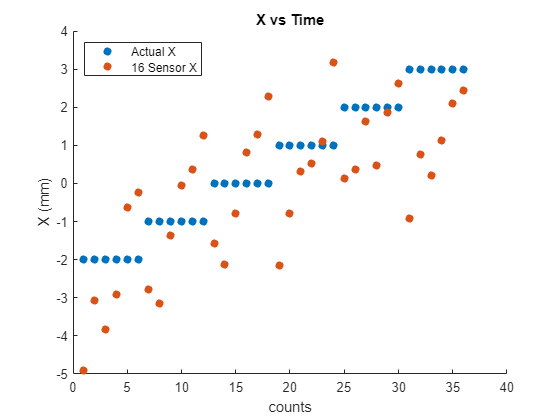

scatter(1:length(multiloc),loc(:,1), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

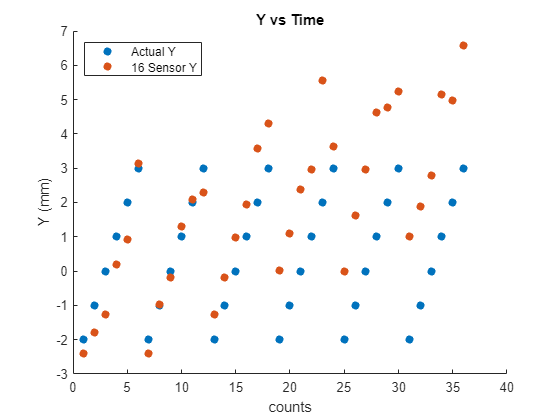

scatter(1:length(multiloc),loc(:,2), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%lim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((multiloc-r0).^2, 2));
zi = [5.000
5.099
5.385
5.831
6.403
7.071
5.099
5.196
5.477
5.916
6.481
7.141
5.385
5.477
5.745
6.164
6.708
7.348
5.831
5.916
6.164
6.557
7.071
7.681
6.403
6.481
6.708
7.071
7.550
8.124
7.071
7.141
7.348
7.681
8.124
8.660
];

r02 = [location(1,1) location(1,2) location(1,3)];
zi2 = sqrt(sum((location-r02).^2, 2));

SSR = sum((zi2 - testx).^2)

SSR =        349.87


SST = sum((zi2 - mean(testx)).^2)

SST =        358.03


R2 = 1 - SSR/SST

R2 =      0.022805


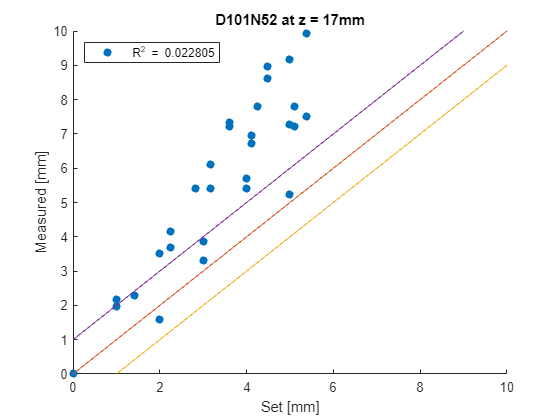


scatter(zi2, testx, 'filled')
hold on;
plot(0:10, 0:10)
plot(0:10, -1:9)
plot(0:10, 1:11)
ylim([0 10])
xlabel("Set [mm]")
ylabel('Measured [mm]')
title('D101N52 at z = 17mm')
legend(['R^2 = ', num2str(R2)], Location = 'northwest')
hold off;

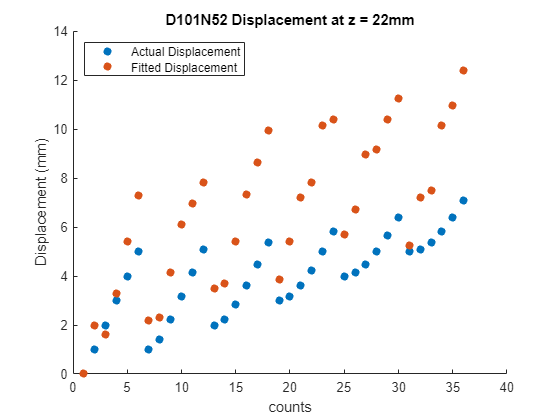


scatter(1:length(zi2), zi2, 'filled')
hold on;
scatter(1:length(testx), testx, 'filled')
title('D101N52 Displacement at z = 22mm')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

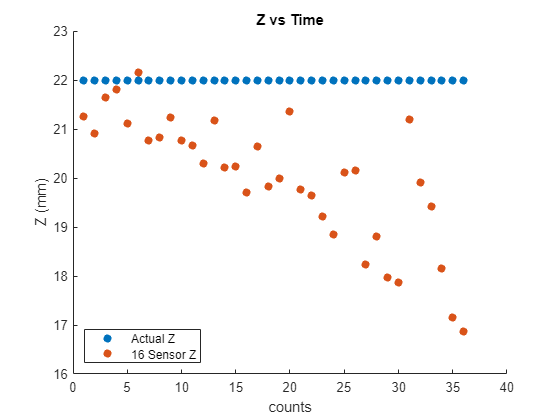

scatter(1:length(multiloc),loc(:,3), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([31,33])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

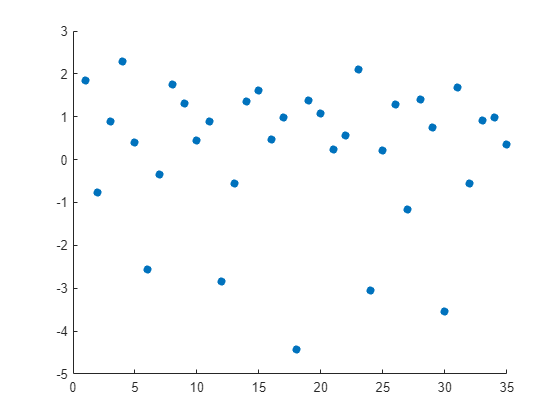

test = diff(multiloc(:,1));
scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -22]

multidisp =       -2.9073     -0.38779     -0.73785
      -1.0677       0.2176      -1.0948
      -1.8269      0.72632     -0.36538
     -0.92667       2.1908     -0.19379
       1.3589       2.9102     -0.87756
       1.7644       5.1287      0.14294
     -0.79015      -0.4163      -1.2265
      -1.1378       1.0191      -1.1706
      0.62104       1.8159     -0.77121
       1.9341       3.2989      -1.2351


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =        3.0244
       1.5446
       1.9997
       2.3866
       3.3296
       5.4256
       1.5172
       1.9245
       2.0683
       4.0186



disp = [4.98 5.08 5.35 5.78 6.34 7.01 5.08 5.18 5.45 5.9 6.46 7.12 5.37 5.47 5.74 6.13 6.66 7.3 5.81 5.91 6.15 6.55 7.05 7.67 6.41 6.47 6.70 7.05 7.55 8.11 7.06 7.13 7.34 7.67 8.1 8.65]'

disp =          4.98
         5.08
         5.35
         5.78
         6.34
         7.01
         5.08
         5.18
         5.45
          5.9


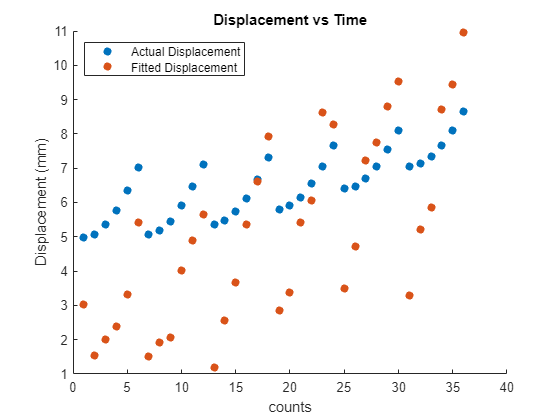


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end